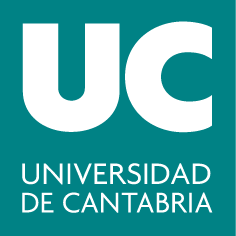

#### ***Grado en Ingeniería ****de Tecnologías de Telecomunicación*

## **G283: Cálculo II**

# **Práctica 8: Soluciones de ecuaciones diferenciales de primer orden**

*Dpto. Matemática Aplicada y Ciencias de la Computación*

### Objetivos	

- Utilizar representaciones gráficas para profundizar en el estudio de las soluciones de una ecuación diferencial de primer orden.

- Analizar las características relativas a monotonía y concavidad de las curvas de una familia uniparamétrica, conociendo únicamente la ecuación diferencial que verifican.

### Resumen teórico

#### Soluciones de una ecuación diferencial

- Solución general de una ecuación diferencial: Es una familia de funciones dependientes de $n$ parámetros (constantes), de la cual pueda extraerse la EDO por derivación y eliminación de los parámetros.

- Solución particular de una ecuación diferencial: Es cada una de las funciones que se obtiene de la solución general al dar valores a los parámetros.

#### Crecimiento y concavidad de las soluciones

Los puntos donde se anula la primera derivada de una función indican cambio en la monotonía, de manera que:

- Soluciones crecientes: $y'>0$

- Soluciones decrecientes: $y'<0 $

La derivada segunda se relaciona con la concavidad, de manera que cuando se anula se obtienen puntos de inflexión:

- Soluciones cóncavas hacia arriba: $y'' >0 $

- Soluciones concavas hacia abajo: $y'' <0$

### Comandos útiles

#### Comando para resolver ecuaciones diferenciales

- `syms y(x)`: crea la variable simbólica `y` que depende de `x`.

- `diff(var, n)`:  Para denotar la derivada de la variable simbólica `var` de orden `n`.

- `dsolve(eq, cond)`: Para resolver ecuaciones diferenciales de forma simbólica. Si se especifica la condición inicial `cond`, se obtiene la solución particular del problema de valor inicial.

Ejemplos:

syms y(x)
solEDO=dsolve(diff(y,x) ==-3*x) 

Si se añade una condición inicial se obtiene la solución particular al problema de valor inicial:

solPVI=dsolve(diff(y,x) ==-3*x, y(0)==1) 

Otra forma de hacerlo es usando cadenas de caracteres en lugar de variable simbólica, pero no se recomienda pues estará obsoleto en futuras versiones: 

dsolve('Dy=-3*x', 'x') % hay que especificar la variable independiente, por defecto t

#### Otros comandos útiles

- `linspace(inicio, fin, N)`: Para crear un vector de N valores conociendo el valor inicial y el final. 

- `plot(x, y, ...)`: Para pintar un vector de valores x frente al vector y, usando las propiedades (color, grosor, etc.) de ...

- `text(x,y,z,'string')`: Para crear una cadena de texto y escribirla sobre un gráfico en la posición de las coordenadas `x,y,z `indicadas.

###  Ejercicios resueltos

**1. Soluciones de una ecuación diferencial**

La expresión $y(x)=C-3cos(2x)$ corresponde a una familia uniparamétrica de curvas porque cada valor real del parámetro *C* proporciona una curva diferente.  

a) Comprueba que todas las curvas de la familia verifican la relación $y'(x)=6sen(2x)$

b) Encuentra la curva de la familia que pasa por el punto $P(1,2)$ (a mano). 

c) Representa una muestra de cuatro curvas junto con la solución particular que pasa por $P$, destacando este punto sobre ella. Las curvas representadas tendrán como dominio el intervalo $[-2\pi, 2\pi]$  y los siguientes valores de $C= -3,-1,1,3$.

a) Comprueba que todas las curvas de la familia verifican la relación $y'(x)=6sen(2x)$

La ecuación diferencial de una familia uniparamétrica de curvas, definida por su ecuación explícita, se obtiene derivando y eliminando la constante en la solución general. En este caso, simplemente derivando desaparece la constante *C* y se obtiene la ecuación diferencial mencionada.

La solución analítica a la ecuación diferencial se calcularía con Matlab:

syms y(x)
solEDO=dsolve(diff(y,x) ==6*sin(2*x)) 

Que coincide con la expresión del enunciado haciendo uso de la relación $cos^{2}x=\frac{1+cos(2x)}{2} \Rightarrow cos(2x)=2cos^{2}x-1$

b) Encuentra la curva de la familia que pasa por el punto $P(1,2)$ (a mano). 

Para encontrar la curva que pasa por el punto $P(1,2)$ basta con determinar la constante imponiendo que la curva pase por $P(1,2)$.


$$ y(x)=C-3cos(2x) \Rightarrow y_{0}(x)=C_{0}-3cos(2x_{0}) \Rightarrow C_{0}=y_{0}+3cos(2x_{0} )$$


Para $P(1,2)$*, * $C_{0}=2 +3cos(2)$

 Por lo tanto, la solución particular que pasa por $P(1,2)$ es: $y_{p}(x)=2 +3cos(2)-3cos(2x)$

c) Representa una muestra de cuatro curvas junto con la solución particular que pasa por $P$, destacando este punto sobre ella. Las curvas representadas tendrán como dominio el intervalo $[-2\pi, 2\pi]$  y los siguientes valores de $C= -3,-1,1,3$.

x=linspace(-2*pi,2*pi); 
figure(1)
for C=-3:2:3  % Bucle con la constante C como contador (-3,-1,1,3)  
    y=C-3*cos(2*x); % Vector de valores de y (ecuación de la solución)
    % Dibuja la solución en azul
    plot(x,y,'b')
    % Sitúa el cursor en las coordenadas (-8,y(1)+0.4) y escribe    
    % la ecuación y=C-3cos(2x) de cada solución particular
    text(-8,y(1)+0.4,['y=',num2str(C),'-3*cos2x'])
    axis equal  
    hold on 
end

% Añadir la solución particular que pasa por el punto P(1,2)
x0=1; y0=2;
plot(x0,y0,'or') % Representa un círculo rojo sobre el punto P
% Calcula la constante C=C0 para la solución particular
c0=y0+3*cos(2*x0); 
yp=c0-3*cos(2*x); % Vector de la solución particular evaluado en todos los x
% Dibuja la solución particular en rojo
plot(x,yp,'r')
title("Soluciones particulares de y'=6*sin(2*x)")
hold off 

**2. Estudiar la monotonía y concavidad de las soluciones de una EDO**

Considerar la ecuación diferencial $y'=x+y$.

a) Encuentra la solución general utilizando Matlab. 

b) Representa las soluciones particulares que pasen por los puntos de la forma $(0,y_{0})$ tomando como dominio el intervalo $[-2,2]$ y los valores de la constante $y_{0}=-5:0.4:5$. Ajusta la ventana al rectángulo $[-2,2]\times[-4,4]$.

c) Estudia la monotonía y la concavidad de las curvas solución. Representa en la figura anterior las curvas que separan regiones de distinto crecimiento y concavidad y comprueba que concuerda con las soluciones representadas en el apartado anterior.

a) Encuentra la solución general utilizando Matlab. 

syms y(x)
solEDO=dsolve(diff(y,x) == x+y) 

b) Representa las soluciones particulares que pasen por los puntos de la forma $(0,y_{0})$ tomando como dominio el intervalo $[-2,2]$ y los valores de la constante $y_{0}=-4:0.4:4$. Ajusta la ventana al rectángulo $[-2,2]\times[-4,4]$.

Para representar las curvas tenemos que hallar la expresión de la constante $C$ en función de las coordenadas de un punto genérico $(x_{0},y_{0})$.


$$y_{0}=C_{0}e^{x_{0}}-x_{0}-1 \Rightarrow C_{0}=(y_{0}+x_{0}+1)e^{-x_{0}}$$


 Por lo tanto, la ecuación de las soluciones particulares, en función de las coordenadas del punto, es: $y=(y_{0}+x_{0}+1)e^{x-x_{0}}-x-1$

Como debemos tomar los puntos de paso de la forma $(0,y_{0})$, es decir, $x_{0}=0$, la ecuación de las soluciones particulares que nos interesan es: $y=(y_{0}+1)e^{x}-x-1$

Representamos ahora las soluciones particulares, para los valores de $y_{0}$ indicados en el enunciado:

%Representación de las soluciones:
x=linspace(-2,2,30); 
figure(2)
for y0=-4:0.4:4 % Puntos de paso de las soluciones particulares con x0=0 
  y=(y0+1)*exp(x)-x-1; % Soluciones que pasan por (0,y0)     
  plot(x,y,'r') % Dibujo de las soluciones 
  hold on
end 
axis([-2 2 -4 4]) 
grid on
title("Soluciones particulares de y'=x+y")

c) Estudia la monotonía y la concavidad de las curvas solución. Representa en la figura anterior las curvas que separan regiones de distinto crecimiento y concavidad y comprueba que concuerda con las soluciones representadas en el apartado anterior.

Sabemos que las soluciones son crecientes cuando la primera derivada es positiva y decrecientes cuando es negativa.

Soluciones crecientes: $y'>0 \Rightarrow x+y >0 \Rightarrow y>-x$

Soluciones decrecientes: $y'<0 \Rightarrow x+y <0 \Rightarrow y<-x$

La recta $y=-x$ divide al plano en dos regiones. A la derecha de dicha recta las soluciones son crecientes y a la izquierda decrecientes (ver recta negra en la siguiente figura).

%Dibuja la recta y=-x en negro
plot(x,-x,'k','LineWidth',2)

Las soluciones son cóncavas hacia arriba si la segunda derivada es positiva y cóncavas hacia abajo si es negativa:

Hallamos la segunda derivada y la expresamos en función de $x, y$: $y''=1+y'=1 +x+y$

Soluciones cóncavas hacia arriba: $y'' >0 \Rightarrow 1 +x+y>0 \Rightarrow y>-x-1$

Soluciones cóncavas hacia abajo: $y'' <0 \Rightarrow 1 +x+y<0 \Rightarrow y<-x-1$

La recta $y=-x-1$ divide al plano en dos regiones. A la derecha de dicha recta las soluciones son cóncavas hacia arriba y a la izquierda cóncavas hacia abajo (ver recta azul en la siguiente figura).

%Dibuja la recta y=-x-1 en azul
plot(x,-x-1,'b','LineWidth',2)
title("Soluciones particulares, monotonía y concavidad de y'=x+y")
hold off

Se comprueba que por encima de la recta negra las soluciones son crecientes y por debajo decrecientes, y que por encima de la azul son cóncavas hacia arriba y por debajo cóncavas hacia abajo.